importPath = 'E:\OpenMIIR-RawEEG_v1\OpenMIIR\eeg\mne';
outputPath = 'E:\OpenMIIR-RawEEG_v1\OpenMIIR\eeg\mne';

subject = 'P01';
rawdataFilename = fullfile(importPath, [subject '-eegdata.mat']);
eventsFilename = fullfile(importPath, [subject '-events.mat']); 
srate = 512.0;

## import raw data - does not work

******************************************************


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\zx305\eeg_options.m


Retrieving plugin versions from server...
Retreiving download statistics...
Cannot connect to the Internet to retrieve statistics for extensions
Cannot connect to the Internet to retrieve extension list


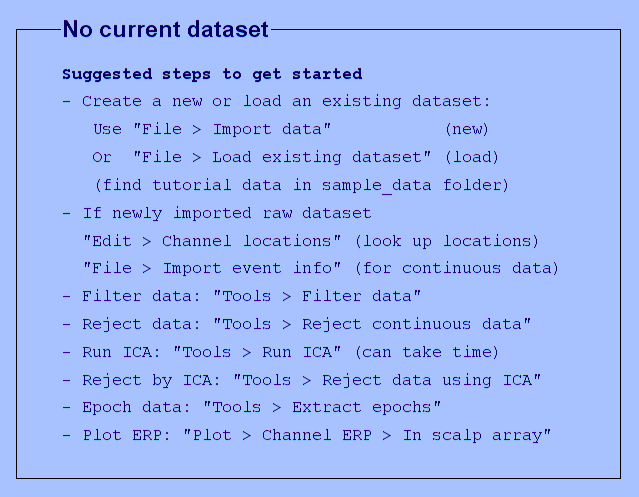

eeglab

fprintf('\nImporting raw data from %s...\n', rawdataFilename)


Importing raw data from E:\OpenMIIR-RawEEG_v1\OpenMIIR\eeg\mne\P01-eegdata.mat...


% EEG = pop_importegimat(rawdataFilename, srate, 0, 'data'); % this does not work here, but in the GUI
EEG = pop_importegimat(); 
% use the GUI so select the file and set the sample rate
EEG.setname = [subject '_imported'];
EEG = eeg_checkset( EEG );

## remove stim channel

EEG = pop_select( EEG,'channel', [1:68] ); 

引用了不存在的字段 'data'。

出错 pop_select (line 121)
if isempty(EEG(1).data)

% TODO: this needs to be adapted if mastoid channels are to be kept
EEG = eeg_checkset( EEG );

## set channel locations

EEG = pop_chanedit( EEG, 'load',{'biosemi64_NoM.locs' 'filetype' 'autodetect'});
EEG = eeg_checkset( EEG );

## import events

events = load(eventsFilename);
events = events.data;
imported = [];
for i = 1:length(events)
    imported = [imported, struct( ...
                            'type', events(i,1), ...
                            'latency', events(i,2), ...
                            'urevent', '')];
end
EEG.event = imported;

## save a copy

EEG = eeg_checkset( EEG );
EEG = pop_saveset( EEG, 'filename',[EEG.setname '.set'],'filepath', outputPath);
EEG = eeg_checkset( EEG );

## update GUI

eeglab redraw